# `Double lane Change Manuever`

`Brian Lesko`

`Masters of Mechanical Engineering`

`Ohio State University `

`April 4, 2023`

`Dr. Levent Guvenc`

`Originally a Matlab and Simulink mardown file`

`By Brian Lesko, Graduate researcher and Teaching associate, Masters of mechanical engineering student`

`Inspired by Robust Controls of Mechatronic Systems, by Dr. Levent Guvenc`

# `Contents`

- `Contents`

- `Introduction `

- `Vehicle Parameters`

- `Simulink Model`

- `Controller Tuning `

- `Path Smoothness`

- `Effect of Vehicle Speed, Simulations `

- `Effect of Preview Length, Simulations`

- `Conclusion`

- `Functions`

# `Introduction`

`    The ability to accurately follow a given path enhances the safety and efficiency of the vehicle and also improves passenger comfort. To achieve optimal path-following performance, it is essential to properly tune the vehicle controller and shape the input path. By ensuring that the input path possesses a smooth derivative, sudden changes in the vehicle's motion can be minimized, thus preventing abrupt acceleration, deceleration, or steering actions. Consequently, an appropriately designed and tuned vehicle controller, combined with a well-shaped input path, contributes to a more seamless and enjoyable driving experience while maintaining safety and precision.`

# `Vehicle Parameters`

clc; clear; close all;
addpath('simulinkModels');
[L, g, Lr, Lf, Cf, Cr, m, J, mu, R, Cs, V, ls, a11, a12, a21, a22, b11, b12, b21, b22, e2, A_matrix, B_matrix, C_matrix, D_matrix] = getModel();

# `Simulink Model`

**Path Following Vehicle Model**

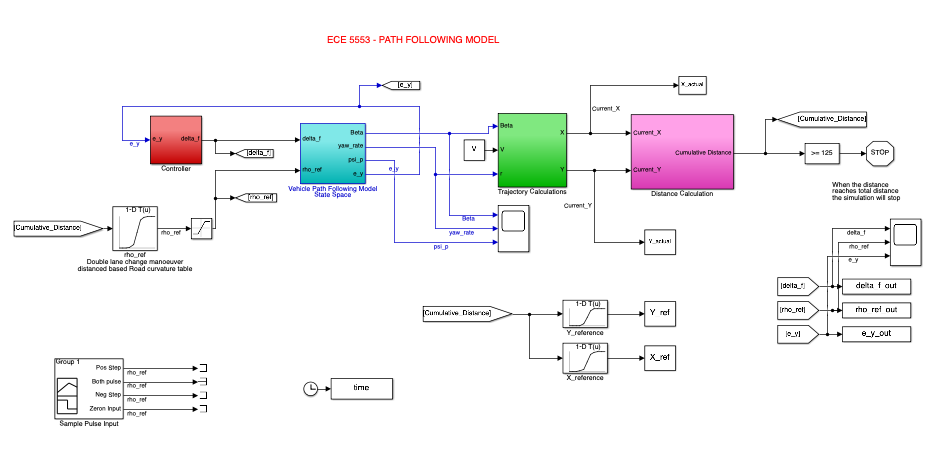

This path following model was provided without a tuned controller or path, the goal in this document is to shape the input path and controller to follow the double lane change manuever

# `Controller Tuning`

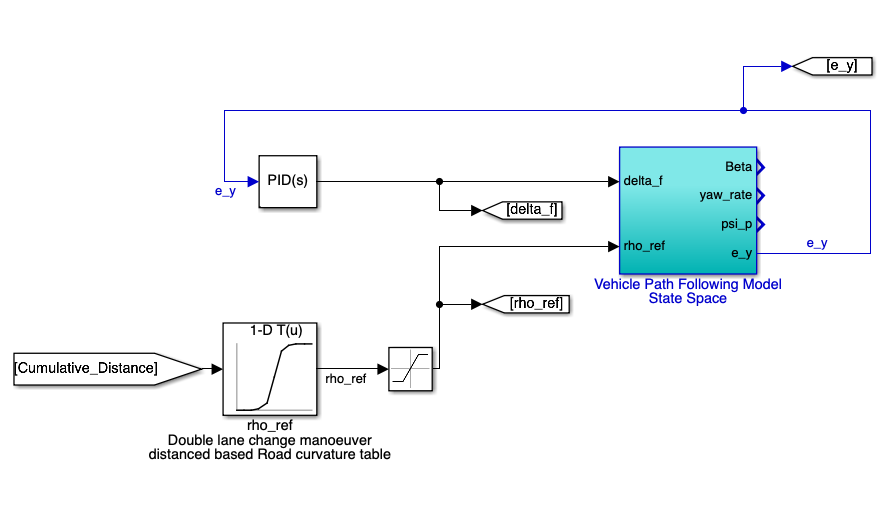

This subsection of the simulink model is extracted to utilize simulink's built in tuning feature, this extraction is necessary because the entire model cannot be linearized due to nonlinearity in the trajectory calculation block.

% which result in the gains as follows, when a lower robustness and higher
% speed is chosen
P = -1;
I = -4.5;
D = 0.0113;
N = 200;

# `C0 Continuous Path`

`C0 refers to a continuous path in the first derivative only. The path is generated by connecting bezier curves. `

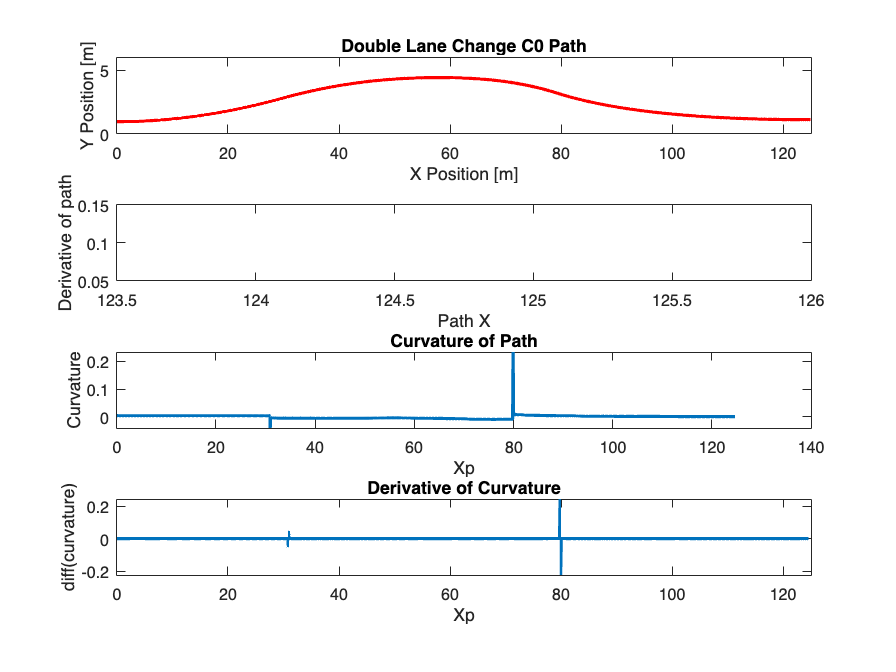

% Path Generation
[Xp,Yp] = getC0Path();
figure(); subplot(411),plot(Xp,Yp,'Linewidth',2,'Color','red'),xlabel('X Position [m]'),ylabel('Y Position [m]')
axis([0 125 0 6]), title('Double Lane Change C0 Path')

subplot(412), plot(Xp(end-1),diff(Yp)), xlabel('Path X'),ylabel('Derivative of path')

% Path Curvatures are needed for the Simulink Model
path_curvatures = getPathCurvature(Xp,Yp);
subplot(413),plot(Xp(1:end-2),path_curvatures,'Linewidth',2), xlabel('Xp'), ylabel('Curvature'), title('Curvature of Path')

% Cumulative Distance travelled at each point along the path
cumulative_distances = getCumulativeDistances(Xp,Yp); % the simulink uses this variable in a lookup table 
dis_vec = cumulative_distances(1:end-1); % the model uses only n-2 entries in its lookup table because curvature loses two entries

% Curvature Slope
subplot(414)
plot(Xp(1:end-3),diff(path_curvatures),'Linewidth',2); xlabel('Xp'), ylabel('diff(curvature)'), xlim([0 125]), title('Derivative of Curvature')

Visually, this path is pretty smooth, but the curvature values are discontinuous because of the supobtimal generation method using splines that are not forced to be smooth.

# `Effect of Vehicle Speed on Path Performance `

Varying vehicle velocity with the preview length of 2m

With the controller tuned for V = 5 m/s , the path is followed well at this speed, but, the following simulation results show that the controller must be retuned for different speed ranges. The path is less followed with a higher speed, and the path is over followed at a lower speed.

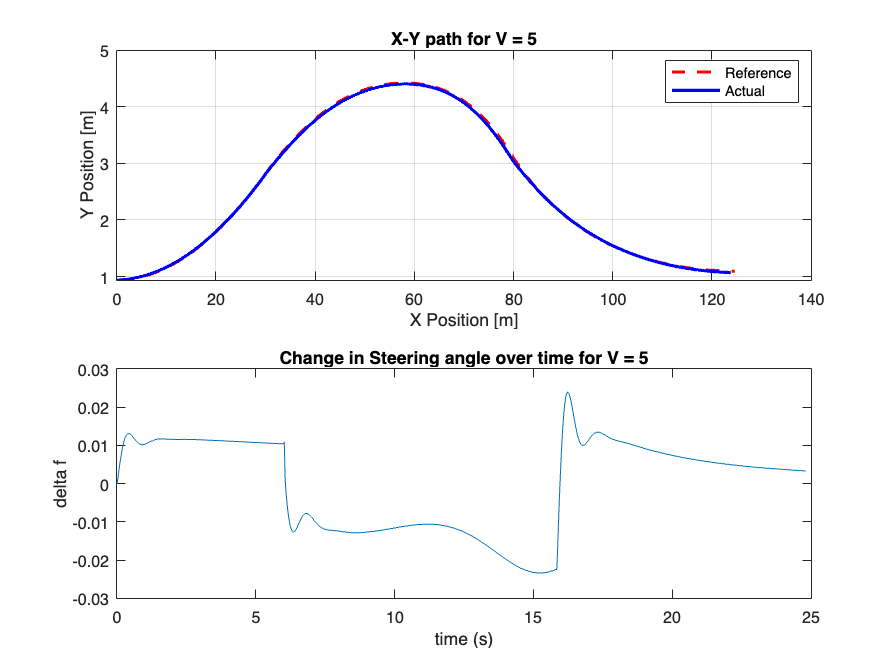

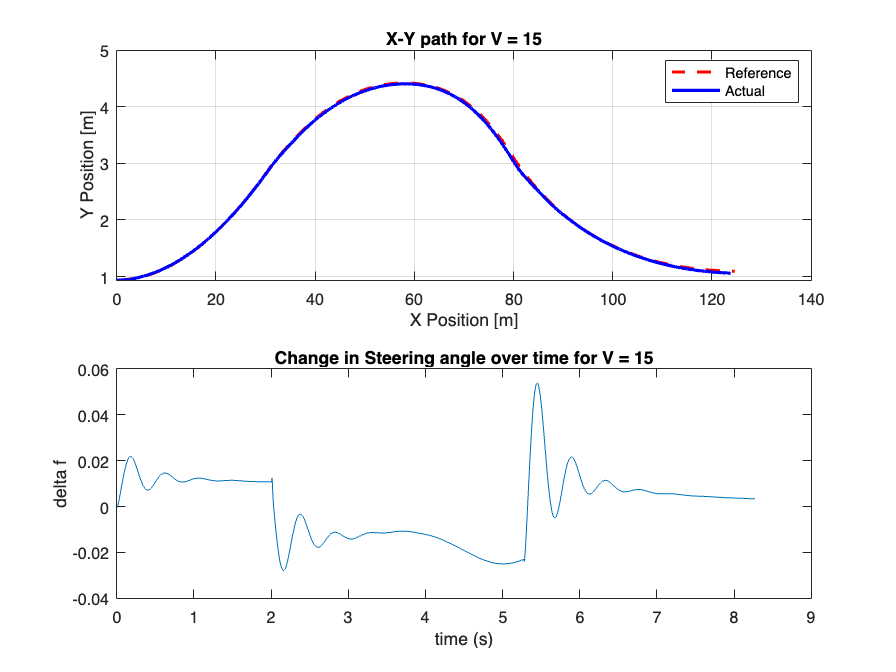

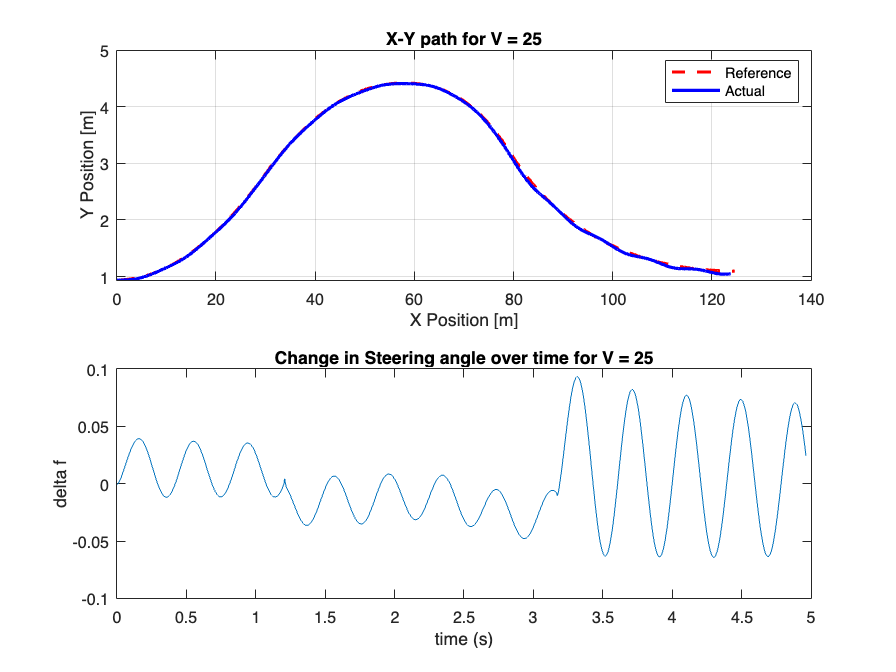

%%Operating condition
ls = 2; %Preview Distance [m]

loop = 1;
Velocities = [5,15,25];
n = length(Velocities);
for V = Velocities
    figure(), hold off
    
    [A_matrix, B_matrix, C_matrix, D_matrix] = changeModel(V,ls);
    sim('Path_following_Model_w_dbl_lane_change');

    % actual vs refrence path
    subplot(2,1,1), plot(X_ref,Y_ref,'r--','Linewidth',2); hold on; grid on; plot(X_actual,Y_actual,'b','Linewidth',2); grid on; hold off
    legend('Reference','Actual'),xlabel('X Position [m]'),ylabel('Y Position [m]'),title(['X-Y path for V = ', num2str(V)]);

    % plot Steering angle change 
    subplot(2,1,2), plot(time,delta_f_out)
    xlabel('time (s)'), ylabel('delta f'), title(['Change in Steering angle over time for V = ', num2str(V)]);

    loop = loop + 1;
end 

   The path is followed well at each tested speed; however, the change in steering angle becomes unstable as the speed increases. Is the oscillation primarily caused by the controller sensitivity, the path smoothness, or some other factor? 

# `Effect of Preview Length `

Varying the preview length 			

input road curvature is “Both pulse” given in the Pulse input block. Plot Steering angle, road curvature disturbance and error 

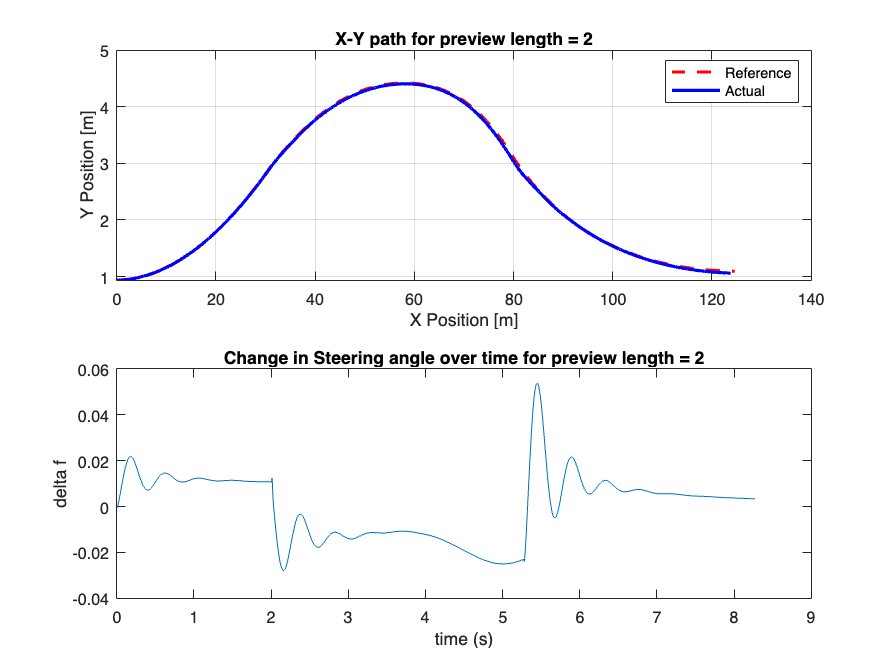

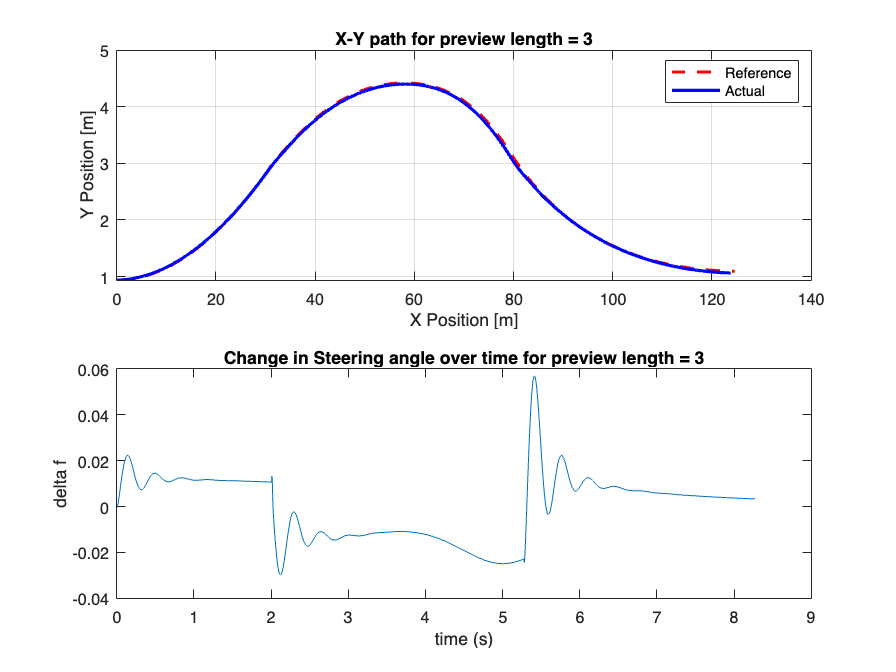

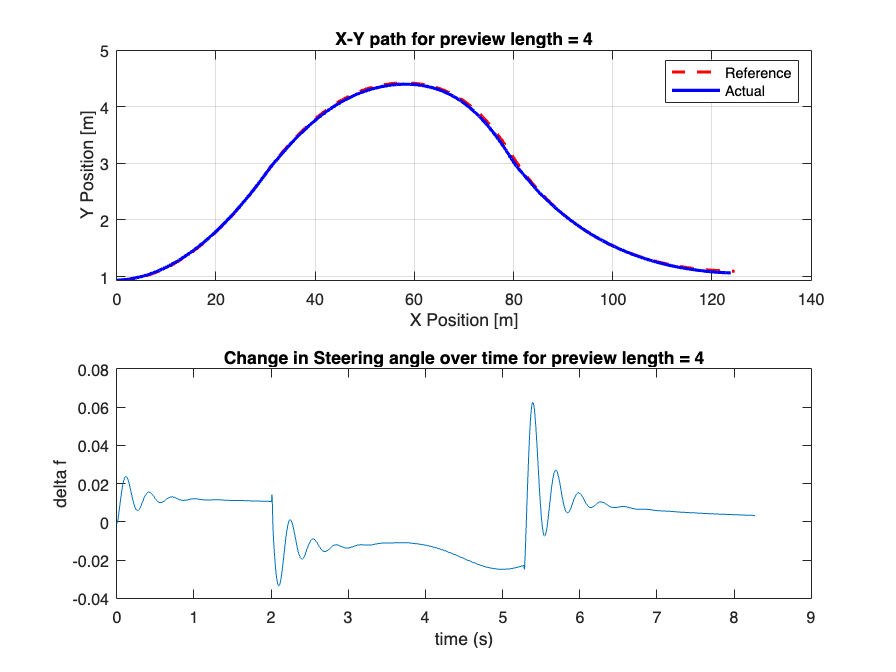

figure
%%Operating condition
V = 15; % m/s or 33 mph

loop = 1;
previewLengths = [2,3,4];
n = length(previewLengths);
for ls = previewLengths
    figure(), hold off

    [A_matrix, B_matrix, C_matrix, D_matrix] = changeModel(V,ls);
    sim('Path_following_Model_w_dbl_lane_change');

    % actual vs refrence path
    subplot(2,1,1) % 3 rows, n columns of graphs, and the index for the graph placement
    plot(X_ref,Y_ref,'r--','Linewidth',2); hold on; grid on; plot(X_actual,Y_actual,'b','Linewidth',2); grid on; hold off
    legend('Reference','Actual'),xlabel('X Position [m]'),ylabel('Y Position [m]'),title(['X-Y path for preview length = ', num2str(ls)]);

    % plot Steering angle change 
    subplot(2,1,2)
    plot(time,delta_f_out)
    xlabel('time (s)'), ylabel('delta f'), title(['Change in Steering angle over time for preview length = ', num2str(ls)]);

    drawnow 

    fig(loop) = gcf;
    loop = loop + 1;
end

The preview length of 3 seems to be the best choice for V = 15 m/s and the given vehicle parameters,  while the preview length of 2 performed best for V = 5 m/s providing evidence that the preview length should increase with velocity. 

# `Why are splines a better solution than sine or cosine? `

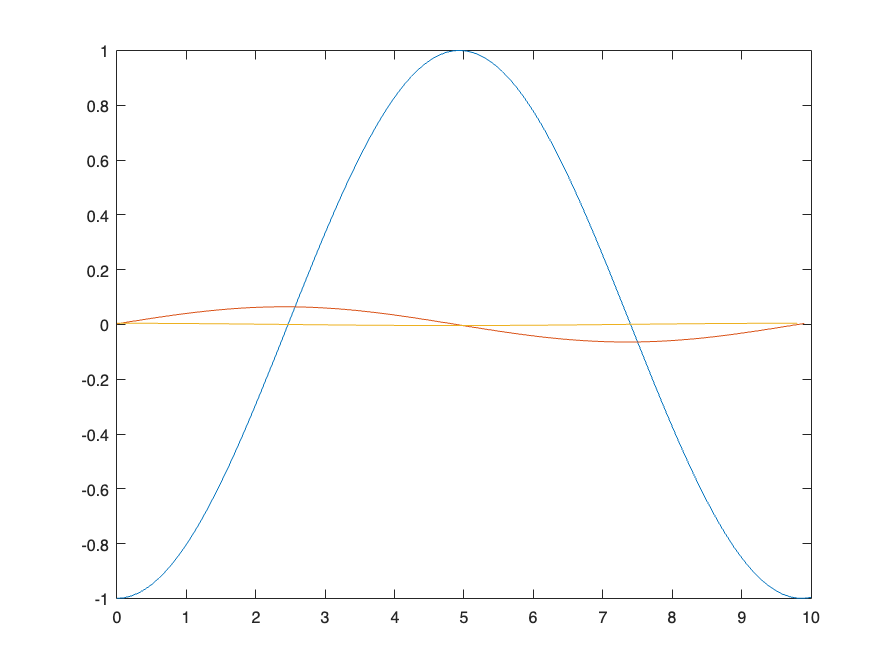

x = linspace(0,10,100);
pi = 3.14;
y = -cos(2*x/pi);

figure()
plot(x,y)
y_d = diff(y);
hold on, plot(x(1:99),y_d)
hold on, plot(x(1:98),diff(y_d))

A modified Cosine wave will not be C2 continuous at its endpoint when connected with a straight line. Which is why splines are a better option for C1 continuity and greater.

# C2 Continuity should provide better performance

% Create 2C path
control_points = [0,0; 15,0;45,3.5; 53,3.5; 63,3.5; 70,3.5; 95,0; 125,0;];
num_points = 1500;
[x, y] = create_c2_curve(control_points, num_points);

% Plotting 
figure(),subplot(3,1,1),plot(x,y,'Linewidth',2), title('C2 Continuous Curve'), xlabel('X (m)'), ylabel('Y (m)')
Xp = x;
Yp = y;

%Road Curvature Calculations
path_curvature = getPathCurvature(Xp,Yp);
subplot(3,1,2), plot(Xp(1:end-2),path_curvature), xlabel('Xp'),ylabel('path curvature')

cumulative_distances = getCumulativeDistances(Xp,Yp);

% checking that the curvature slope is okay
subplot(3,1,3)
plot(diff(path_curvature),'Linewidth',2); xlabel('points'), ylabel('diff(rho_new)'), title('Derivative of Road Curvature')

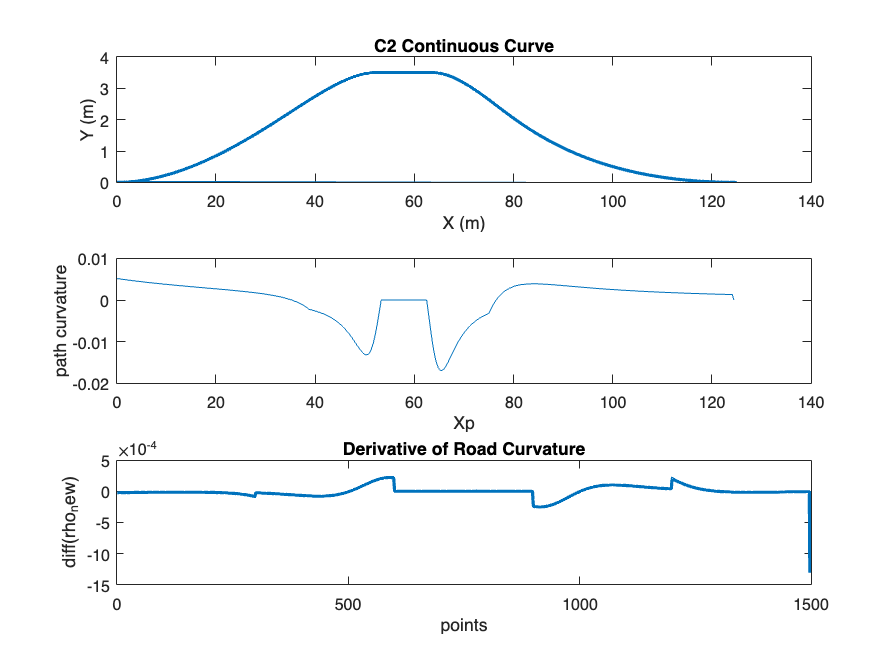

V = 5;

ls = 2;
[A_matrix, B_matrix, C_matrix, D_matrix] = changeModel(V,ls);
sim('Path_following_Model_w_dbl_lane_change');
figure()
    % actual vs refrence path
    subplot(2,1,1), plot(X_ref,Y_ref,'r--','Linewidth',2); hold on; grid on; plot(X_actual,Y_actual,'b','Linewidth',2); grid on; hold off
    legend('Reference','Actual'),xlabel('X Position [m]'),ylabel('Y Position [m]'),title(['X-Y path for V = ', num2str(V)]);

    % plot Steering angle change 
    subplot(2,1,2), plot(time,delta_f_out)
    xlabel('time (s)'), ylabel('delta f'), title(['Change in Steering angle over time for V = ', num2str(V)]);

# Functions 

Cumulative Distances 

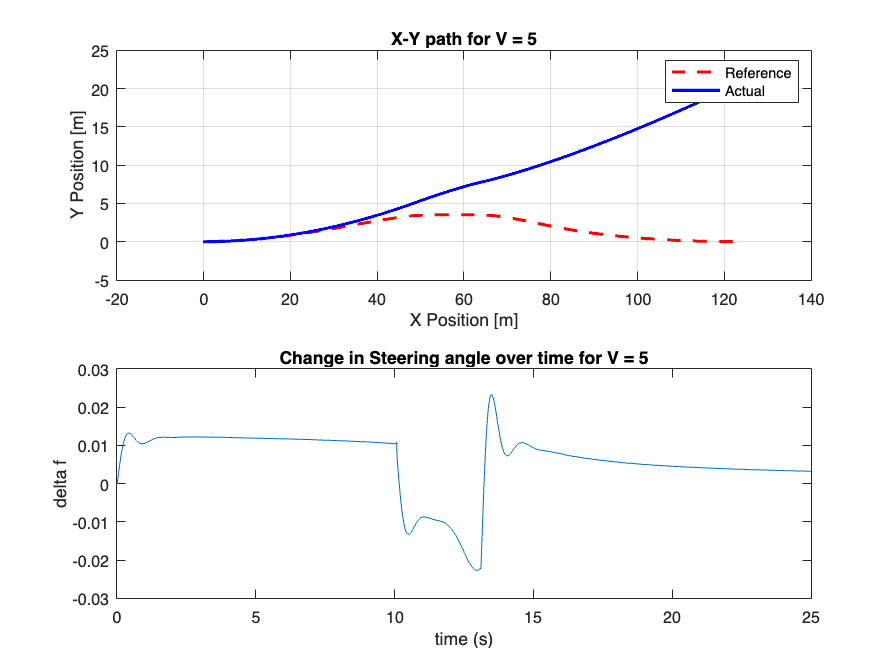

function cumulative_distances = getCumulativeDistances(Xp,Yp)
    % This function calculates the cumulative distances traveled based on Xp and Yp arrays of coordinates


    % Initialize the total distance traveled to 0
    Tot_d = 0;
    
    % Loop through all the points in the input arrays (from the first to the second to last)
    cumulative_distances = zeros(length(Xp)-1,1);
    for j = 1:length(Xp)-1
        % Calculate the Euclidean distance between the consecutive points (j and j+1)
        d(j) = sqrt((Xp(j+1)-Xp(j))^2+(Yp(j+1)-Yp(j))^2); 
        
        % Update the total distance with the calculated distance
        Tot_d = Tot_d + d(j);
        
        % Store the cumulative distance traveled so far in the output array
        cumulative_distances(j) = Tot_d;
    end
end


Vehicle Parameters

function [L, g, Lr, Lf, Cf, Cr, m, J, mu, R, Cs, V, ls, a11, a12, a21, a22, b11, b12, b21, b22, e2, A_matrix, B_matrix, C_matrix, D_matrix] = getModel()
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%ECE 5553 - Autonomy in Vehicles
    %%HW 4 - Path Following Linear Model
    %%Spring 2019
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    %%Vehicle Parameters
    L=2.85; % Distance between the axles [m]
    g=9.81; % 
    Lr = 1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle
    Lf = 1.3; % Distance from the center of gravity of the vehicle (CG) to the front axle
    Cf = 3e5; % Cornering Stiffness of Front Tires
    Cr = 3e5; % Cornering Stiffness of Rear Tires
    m = 2000; %Mass of the vehicle [kg]
    J = 3700; %Yaw moment of Inertia
    mu = 0.7; %Dry coefficient of Friction
    R = 0.3;
    Cs=1.5e5;
    
    %%Operating condition
    V = 5; %Longitudinal Velocity [m/s]
    ls = 2; %Preview Distance [m]
    
    %Linear Parameters Calculation
    a11 = -(Cr+Cf)/(m*V);
    a12 = -1-((Cf*Lf-Cr*Lr)/(m*V^2));
    a21 = (Lr*Cr-Lf*Cf)/J;
    a22 = -((Cf*Lf^2)+(Cr*Lr^2))/(V*J);
    b11 = Cf/(m*V); %Only Front wheel steering
    b12 = 0; %delta_r parameter
    b21 = Cf*Lf/J; %Only Front wheel steering
    b22 = 0; %delta_r parameter
    e2 = 1/J; % For yaw moment term - Not used in Path following model currently
    
    %%%%State Space Representation
    A_matrix = [a11 a12 0 0; a21 a22 0 0; 0 1 0 0; V ls V 0];
    B_matrix = [b11 0; b21 0; 0 -V; 0 -ls*V];
    C_matrix = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]; %Output is beta, r and ey
    D_matrix = [0 0; 0 0; 0 0; 0 0];
end 

# Change Vehicle Parameters

function [A_matrix, B_matrix, C_matrix, D_matrix] = changeModel(V,ls)
    
    %%Vehicle Parameters
    L=2.85; % Distance between the axles [m]
    g=9.81; % 
    Lr = 1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle
    Lf = 1.3; % Distance from the center of gravity of the vehicle (CG) to the front axle
    Cf = 3e5; % Cornering Stiffness of Front Tires
    Cr = 3e5; % Cornering Stiffness of Rear Tires
    m = 2000; %Mass of the vehicle [kg]
    J = 3700; %Yaw moment of Inertia
    mu = 0.7; %Dry coefficient of Friction
    R = 0.3;
    Cs=1.5e5;
    
    %Linear Parameters Calculation
    a11 = -(Cr+Cf)/(m*V);
    a12 = -1-((Cf*Lf-Cr*Lr)/(m*V^2));
    a21 = (Lr*Cr-Lf*Cf)/J;
    a22 = -((Cf*Lf^2)+(Cr*Lr^2))/(V*J);
    b11 = Cf/(m*V); %Only Front wheel steering
    b12 = 0; %delta_r parameter
    b21 = Cf*Lf/J; %Only Front wheel steering
    b22 = 0; %delta_r parameter
    e2 = 1/J; % For yaw moment term - Not used in Path following model currently
    
    %%%%State Space Representation
    A_matrix = [a11 a12 0 0; a21 a22 0 0; 0 1 0 0; V ls V 0];
    B_matrix = [b11 0; b21 0; 0 -V; 0 -ls*V];
    C_matrix = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]; %Output is beta, r and ey
    D_matrix = [0 0; 0 0; 0 0; 0 0];
end 

# Path Curvatures

function path_curvatures = getPathCurvature(Xp, Yp)
    % Road Curvature Calculations

    % Input: Xp and Yp are vectors containing the X and Y coordinates of the path points
    % Output: path_curvatures is a vector containing the curvature values for each point in the path

    % Check if Xp and Yp have the same length
    if length(Xp) ~= length(Yp)
        error('Input vectors Xp and Yp must have the same length.');
    end

    % Compute the first-order differences (derivatives)
    d_Xp = diff(Xp);
    d_Yp = diff(Yp);

    % Compute the second-order differences (second derivatives)
    dd_Xp = diff(Xp, 2);
    dd_Yp = diff(Yp, 2);

    % Curvature formula given in Lecture 21, Slide 27
    % (d_Xp * dd_Yp - d_Yp * dd_Xp) / ((d_Xp^2 + d_Yp^2)^(3/2))
    path_curvatures = (d_Xp(2:end) .* dd_Yp - d_Yp(2:end) .* dd_Xp) ./ (d_Xp(2:end).^2 + d_Yp(2:end).^2).^1.5;
end

# C0 continuous path 

function [Xp,Yp] = getC0Path()
    %Initialize the variables
    Xp = [];
    Yp = [];
    
    %%%%%%%
    %DOUBLE LANE CHANGE MANOEUVER - ISO 3888-1
    %%%%%%%
    Veh_width = 1.57; %For a Mid-size Sedan Vehicle, width in m
    L1 = Veh_width*1.1+0.15;
    L2 = Veh_width*1.2+0.15;
    L3 = Veh_width*1.3+0.15;
    
    p = []; 
    
    %Change the points here to modify the shape of the curve.
    %If you are adding new points, make sure you modify the p & p_ub_pts array
    %points accordingly
    p_lb_pts = [0,0; 15,0; 31,2; 45,3.5; 53,3.5; 63,3.5; 70,3.5; 80,2; 95,0; 125,0;]; %Points on the curve considering 0,0 starting point and no offset L1,L2,L3
    %p_lb_pts = [0,0; 15,0; 31.25,1.95; 45,3.5; 53,3.5; 63,3.5; 70,3.5;81.75,1.95; 95,0; 125,0;]; % good path!
    %p_lb_pts = [0,0; 15,0; 31,2; 45,3.5; 53,3.5; 63,3.5; 70,3.5; 80,2; 95,0;125,0;]; %best path so far
    
    p_ub_pts = p_lb_pts;
    p = p_lb_pts;
    
    %Upper Bound
    p_ub_pts(1:3,2) = p_lb_pts(1:3,2)+(L1); %Offset of the path. upper bound
    p_ub_pts(4:7,2) = p_lb_pts(4:7,2)+(L2); %Offset of the path. upper bound
    p_ub_pts(8:10,2) = p_lb_pts(8:10,2)+(L3); %Offset of the path. upper bound
    
    %Mid-path
    p(1:3,2) = p_lb_pts(1:3,2)+(L1/2); %Offset of the path to the centre of the vehicle
    p(4:7,2) = p_lb_pts(4:7,2)+(L2/2); %Offset of the path to the centre of the vehicle
    p(8:10,2) = p_lb_pts(8:10,2)+(L3/2); %Offset of the path to the centre of the vehicle
    
    %Split the points into three bezier curves%
    
    %Beizer Curves passes through first and last points and approximates
    %through the middle points. This is the characteristic of the Beizer curve
    p1 = p(1:3,:); 
    p2 = p(3:8,:);
    p3 = p(8:10,:);
    
    
    [Xp_1,Yp_1] = bezier_curve(p1); %For first curve
    [Xp_2,Yp_2] = bezier_curve(p2); %For second curve
    [Xp_3,Yp_3] = bezier_curve(p3); %For third curve

    Xp = [Xp_1(1:end-1); Xp_2(1:end-1); Xp_3(1:end-1);]; 
    Yp = [Yp_1(1:end-1); Yp_2(1:end-1); Yp_3(1:end-1);];
end 

# Create a bezier curve between points

function [Xp,Yp] = bezier_curve(p1)
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%ECE 5553 - Autonomy in Vehicles
    %%HW 4 - Path Following Linear Model
    %%Spring 2019
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%Bezier curve for higher order polynomials%
    % https://ocw.mit.edu/courses/electrical-engineering-and-computer-science/6-837-computer-graphics-fall-2012/lecture-notes/MIT6_837F12_Lec01.pdf
    % Refer to Slide 62
    
    %   Detailed explanation goes here
    p = p1;
    
    n = length(p); %number of points
    n1=n-1;
    
    for i=0:1:n1
    sigma(i+1)=factorial(n1)/(factorial(i)*factorial(n1-i));  % for calculating (x!/(y!(x-y)!)) values 
    end
    l=[];
    UB=[];
    for u=0:0.002:1
        for d=1:n
        UB(d)=sigma(d)*((1-u)^(n-d))*(u^(d-1));
        end
    l=cat(1,l,UB);                                       
    end
    P=l*p;
    
    Xp = [P(:,1)]; %X_reference Points
    Yp = [P(:,2)]; %Y_reference Points
end

# C2 Continuity Functions

function [x, y] = create_c2_curve(control_points, num_points)
    % Ensure control_points is a N x 2 matrix
    assert(size(control_points, 2) == 2, 'Control points must be a N x 2 matrix');
    % Generate a knot vector with C3 continuity (k = 4)
    num_control_points = size(control_points, 1);
    k = 4;
    knot_vector = [zeros(1, k-1), linspace(0, 1, num_control_points - k + 2), ones(1, k-1)];
    % Create the B-spline basis functions
    t = linspace(0, 1, num_points);
    B = bspline_basis_functions(t, knot_vector, k);
    % Calculate the curve points
    curve_points = B * control_points;
    % Separate x and y coordinates
    x = curve_points(:, 1);
    y = curve_points(:, 2);
end
function B = bspline_basis_functions(t, knot_vector, k)
    n = length(knot_vector) - k;
    B = zeros(length(t), n);

    for i = 1:n
        for j = 1:length(t)
            B(j, i) = de_boor_cox(t(j), i, k, knot_vector);
        end
    end
end
function val = de_boor_cox(x, i, k, knot_vector)
    if k == 1
        val = double(knot_vector(i) <= x && x < knot_vector(i + 1));
    else
        term1 = 0;
        term2 = 0;
        denominator1 = knot_vector(i + k - 1) - knot_vector(i);
        denominator2 = knot_vector(i + k) - knot_vector(i + 1);
        if denominator1 ~= 0
            term1 = ((x - knot_vector(i)) / denominator1) * de_boor_cox(x, i, k - 1, knot_vector);
        end
        if denominator2 ~= 0
            term2 = ((knot_vector(i + k) - x) / denominator2) * de_boor_cox(x, i + 1, k - 1, knot_vector);
        end
        val = term1 + term2;
    end
end

# C3 Continuity Path Functions 

function [x, y] = create_c3_curve(control_points, num_points)
    % Ensure control_points is a N x 2 matrix
    assert(size(control_points, 2) == 2, 'Control points must be a N x 2 matrix');

    % Generate a knot vector with C3 continuity (k = 6)
    num_control_points = size(control_points, 1);
    k = 6;
    knot_vector = [zeros(1, k-1), linspace(0, 1, num_control_points - k + 2), ones(1, k-1)];

    % Create the B-spline basis functions
    t = linspace(0, 1, num_points);
    B = bspline_basis_functions3(t, knot_vector, k);

    % Calculate the curve points
    curve_points = B * control_points;

    % Separate x and y coordinates
    x = curve_points(:, 1);
    y = curve_points(:, 2);
end

function B = bspline_basis_functions3(t, knot_vector, k)
    n = length(knot_vector) - k;
    B = zeros(length(t), n);

    for i = 1:n
        for j = 1:length(t)
            B(j, i) = de_boor_cox3(t(j), i, k, knot_vector);
        end
    end
end

function val = de_boor_cox3(x, i, k, knot_vector)
    if k == 1
        val = double(knot_vector(i) <= x && x < knot_vector(i + 1));
    else
        term1 = 0;
        term2 = 0;
        denominator1 = knot_vector(i + k - 1) - knot_vector(i);
        denominator2 = knot_vector(i + k) - knot_vector(i + 1);

        if denominator1 ~= 0
            term1 = ((x - knot_vector(i)) / denominator1) * de_boor_cox(x, i, k - 1, knot_vector);
        end

        if denominator2 ~= 0
            term2 = ((knot_vector(i + k) - x) / denominator2) * de_boor_cox(x, i + 1, k - 1, knot_vector);
        end

        val = term1 + term2;
    end
end